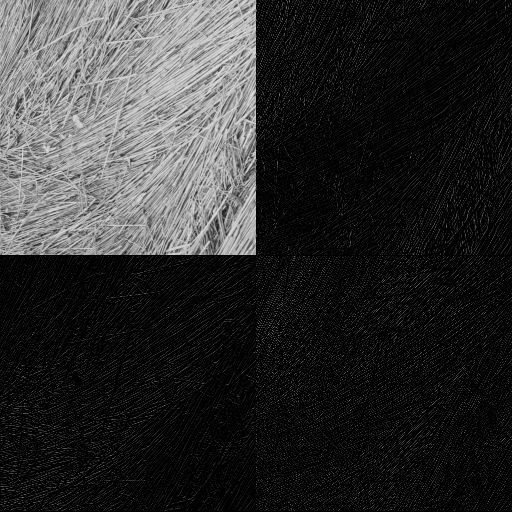

%  读文件
I=imread("image/textures/1.1.03.tiff");
I1=I;
[M,N]=size(I);
[aa,bb,cc,dd]=IWT(I1);
C2=[aa,bb;cc,dd];
imshow(uint8(C2))

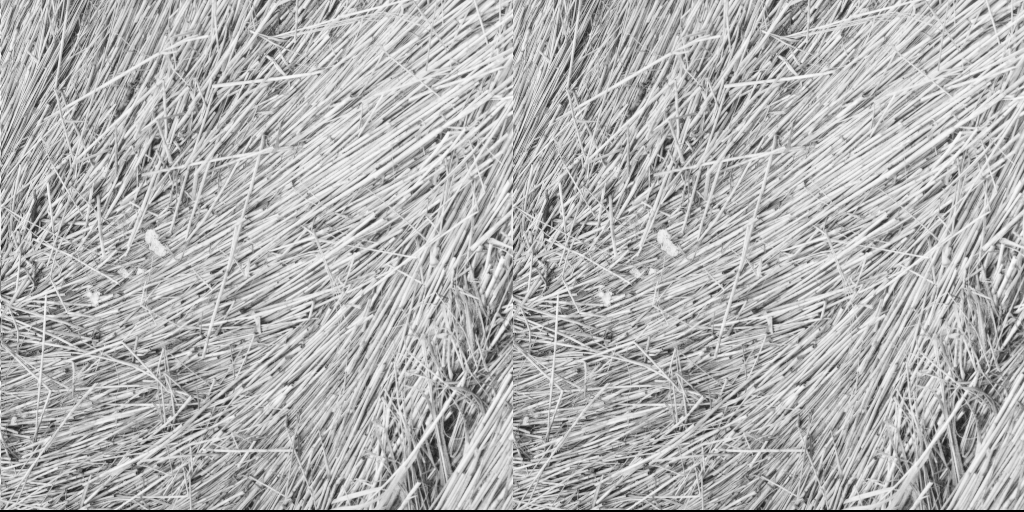

C3=IIWT(C2(1:M/2,1:N/2),C2(1:M/2,(N/2+1):N),C2((M/2+1):M,1:N/2),C2((M/2+1):M,(N/2+1):N));
imshowpair(uint8(C3),I,"montage") 

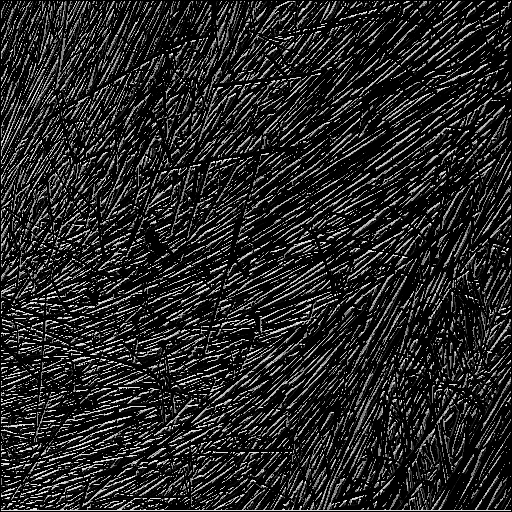

B=LBP(I,23);
imshow(uint8(B))

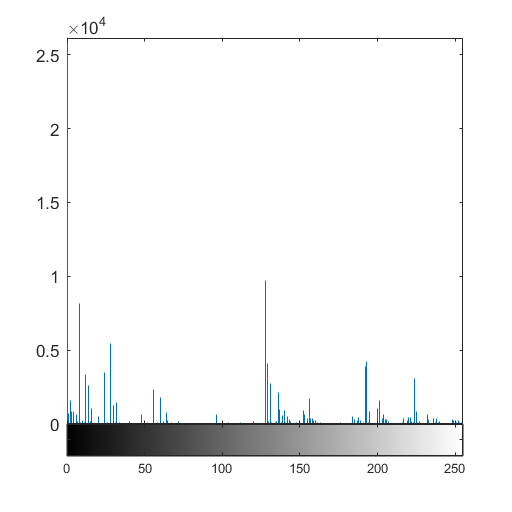

imhist(uint8(B))

B1=double(B==0);
SUM(B1)/(512*512)  

ans = 0.6342